clear all
syms x(t) y(t) T(t)

%Set up everything.

m=1; r=2; g=1;

eqn1 = m*diff(x(t), 2) == T(t)/r*x(t);
eqn2 = m*diff(y(t), 2) == T(t)/r*y(t) - m*g;
eqn3 = x(t)^2 + y(t)^2 == r^2;
DEs=[eqn1;eqn2]; posnConstraints=eqn3;
vars = [y; x; T];

The unknown functions (just the base functions, not derivatives) are: T(t),x(t),y(t)
Multiple feasible initial conditions found:
Dyt: -1.732051    y: 1.732051    
Dyt: 1.732051    y: -1.732051    

Selecting IC:
Dyt:-1.732051    y:1.732051    
Because it is first.  Use a hint if you want to select a different initial condition.

Initial Conditions:
Y0/YP0:
T: -5.133975 Tt:0.000000
x: 1.000000 xt:3.000000
y: 1.732051 yt:-1.732051
Dxt: 3.000000 Dxtt:-2.566987
Dyt: -1.732051 Dytt:-5.446152


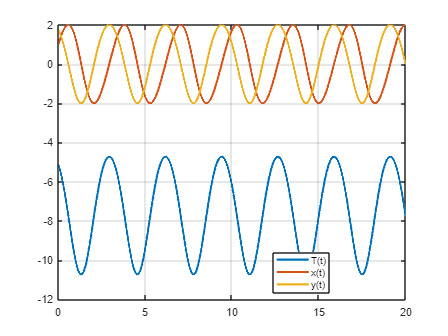

%Tread the problem numerically.  
soln=mechanicsAsDAE(DEs,posnConstraints,[],[0,20],{"x==1","Dxt==3"});

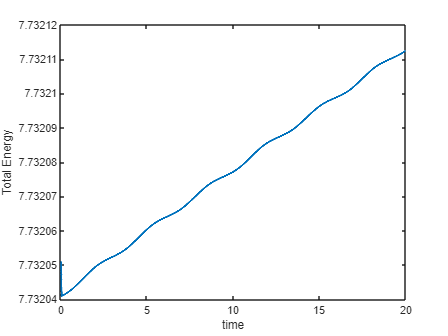

%See if we are conserving energy.
KineticEnergy=1/2*m*(soln.Dxt.^2+soln.Dyt.^2);
PotentialEnergy=m*soln.y*g;
plot(soln.t,KineticEnergy+PotentialEnergy,'LineWidth',2)
xlabel('time'); ylabel('Total Energy')

%Get the general equations of motion. 
clear m r g
syms x(t) y(t) T(t) m r g
eqn1 = m*diff(x(t), 2) == T(t)/r*x(t);
eqn2 = m*diff(y(t), 2) == T(t)/r*y(t) - m*g;
eqn3 = x(t)^2 + y(t)^2 == r^2;

[governingEqs,PP]=analyzeSystem([eqn1,eqn2],eqn3,[],[y,diff(y)])

The unknown functions are:
T(force)
x
y

Expected Number of State Variables:2
Warning! There are multiple branches for Dytt. This likely means that this dynamical system is piecewise-defined in terms of the state variables.  Arbitrarily selecting the first branch.
Warning! There are multiple branches for Dxt. This likely means that this dynamical system is piecewise-defined in terms of the state variables.  Arbitrarily selecting the first branch.
Warning! There are multiple branches for Dxtt. This likely means that this dynamical system is piecewise-defined in terms of the state variables.  Arbitrarily selecting the first branch.
Warning! There are multiple branches for T. This likely means that this dynamical system is piecewise-defined in terms of the state variables.  Arbitrarily selecting the first branch.
Warning! There are multiple branches for x. This likely means that this dynamical system is piecewise-defined in terms of the state variables.  Arbitrarily selecting the first br

$$governingEqs = \frac{\partial^{2}}{\partial t^{2}}y\left(t\right)=\frac{r^{2}\,y\left(t\right)\,{\left(\frac{\partial }{\partial t}y\left(t\right)\right)}^{2}+g\,r^{4}-2\,g\,r^{2}\,{y\left(t\right)}^{2}+g\,{y\left(t\right)}^{4}}{r^{2}\,{y\left(t\right)}^{2}-r^{4}}$$

$$PP = \begin{array}{l} \left(\begin{array}{c} \frac{\partial }{\partial t}x\left(t\right)=\frac{y\left(t\right)\,\frac{\partial }{\partial t}y\left(t\right)}{\sqrt{r^{2}-{y\left(t\right)}^{2}}}\\ \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)=-\frac{\sigma_{2}\,\sigma_{1}}{r^{2}\,\left({y\left(t\right)}^{2}-r^{2}\right)}\\ T\left(t\right)=\frac{m\,\sigma_{1}}{r\,{y\left(t\right)}^{2}-r^{3}}\\ x\left(t\right)=-\sigma_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=r^{2}\,{\left(\frac{\partial }{\partial t}y\left(t\right)\right)}^{2}-g\,r^{2}\,y\left(t\right)+g\,{y\left(t\right)}^{3}\\ \sigma_{2}=\sqrt{\left(r-y\left(t\right)\right)\,\left(r+y\left(t\right)\right)} \end{array}$$

%Substitute specific values into the general equations of motion, and
%time-step. 
specificGoverningEqs=subs(governingEqs,{m,r,g},{1,2,1})

$$specificGoverningEqs = \frac{\partial^{2}}{\partial t^{2}}y\left(t\right)=\frac{4\,y\left(t\right)\,{\left(\frac{\partial }{\partial t}y\left(t\right)\right)}^{2}+{y\left(t\right)}^{4}-8\,{y\left(t\right)}^{2}+16}{4\,{y\left(t\right)}^{2}-16}$$

specificPP=subs(PP,{m,r,g},{1,2,1})

$$specificPP = \begin{array}{l} \left(\begin{array}{c} \frac{\partial }{\partial t}x\left(t\right)=\frac{y\left(t\right)\,\frac{\partial }{\partial t}y\left(t\right)}{\sqrt{4-{y\left(t\right)}^{2}}}\\ \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)=-\frac{\sigma_{2}\,\sigma_{1}}{4\,\left({y\left(t\right)}^{2}-4\right)}\\ T\left(t\right)=\frac{\sigma_{1}}{2\,{y\left(t\right)}^{2}-8}\\ x\left(t\right)=-\sigma_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=4\,{\left(\frac{\partial }{\partial t}y\left(t\right)\right)}^{2}+{y\left(t\right)}^{3}-4\,y\left(t\right)\\ \sigma_{2}=\sqrt{-\left(y\left(t\right)-2\right)\,\left(y\left(t\right)+2\right)} \end{array}$$


%You can time-step this, but notice that you will have big trouble when
%y=+/-2.

soln=timeStepODESystem(specificGoverningEqs,[0,20],{y==1,diff(y)==0},specificPP,0);

The unknown functions (just the base functions, not derivatives) are: y(t)


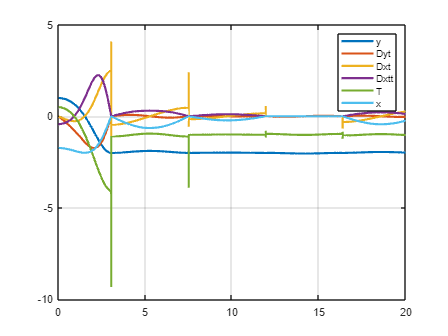

plot(soln.t,soln.y,soln.t,soln.Dyt,soln.t,soln.Dxt,soln.t,soln.Dxtt,soln.t,soln.T,soln.t,soln.x,'LineWidth',2); grid on; legend("y","Dyt","Dxt","Dxtt","T","x")